# Finite horizon constrained control

## Exercise 1

**Exercise text removed** (course material, copyright precaution). Topic: Finite-horizon unconstrained LQ for scalar DT system, Hp=3, Q=S=R=1; compute optimal input sequence and state predictions.

**Compute the optimizing input sequnce and the state ahead prediction, unconstrained**

close all
clear
clc

% Initial data:
A = 0.9048; %weigth 
B = 0.0952; %weight
Ts=0.1; %sampling time
Q = 1;
S = 1;
R = 1;
x_k = 0.2; %initial state
Hp = 3;

Now we have to compute the matrices that build our cost function: A_cal, B_cal, Q_cal and R_cal

NOTE: the formulation of these matrices can be found at slides L08_19-21

Since we have just one input and one state => n = 1 and p = 1

From the data we get Hp = 3 

So now let's compute the matrices

A_cal=[A;A^2;A^3]; % A calligraphic
B_cal=[[B 0 0];[A*B B 0];[A^2*B A*B B]]; % B calligraphic

% Q and R are always block diagonal matrices 
% => we can use matlab function blkdiag
Q_cal=blkdiag(Q,Q,S);   % Q calligraphic
R_cal=blkdiag(R,R,R);   % R calligraphic


% test per vedere se la funzione funziona correttamente
[A_cal_1, B_cal_1, Q_cal_1, R_cal_1] = cal_m_builder(Hp, A,B,R,Q,S);

norm(A_cal - A_cal_1, 2)

ans = 0

norm(B_cal - B_cal_1, 2)

ans = 0

norm(Q_cal - Q_cal_1, 2)

ans = 0

norm(R_cal - R_cal_1, 2)

ans = 0


% e si gode

To calculate H and F we use the formula given in the slide L08_22

H = 2*(B_cal'*Q_cal*B_cal+R_cal);
F = 2*A_cal'*Q_cal*B_cal;

Now we solve in close form:

% the 2 statements do the same thing, but it's better to use the first one
u_k=-H\(F'*x_k)

u_k =    -0.0414
   -0.0272
   -0.0135


%u_k=-inv(H)*(F'*x_k);

Finally, ahead predictions of the state can be computed as

X_k=A_cal*x_k+B_cal*u_k % we are basically writing a common state equation

X_k =     0.1770
    0.1576
    0.1413


NOTE: this problem was uncostrained. In the following example we'll see a **constrained **finite horizon problem

## Exercise 2

**Exercise text removed** (course material, copyright precaution). Topic: Same finite-horizon problem with input constraint |u|<=0.02; compute optimal sequence and state predictions.

We have the same exercise as before but with constraints:  -0.02=<u(k)=<0.02

In the previous exercise we have obtained:

u_k =

  -0.0414 -> Uk

  -0.0272 -> Uk+1

  -0.0135 -> Uk+2

We can see that two of our components violate our bounds!!!!

So we must consider constraints (a set of linear inequalities in the variable U)

NOTE: in this exercise, our constraints are just linked to** input saturation**. It is possible to have also **state constraints **(again expressed with a set of linear inequalities in the variable U) but this is not the case 

The set of inequalities can be written in a compact form with matrices. In particular we can write that 

G*U <= h

G = [eye(3);-eye(3)];
h = 0.02*ones(6,1); % Column matrix with 3 min values and 3 max values.

H = (H+H')/2; 
% why did we do it? H must be symmetric. With this passage we "force"
% symmetry
% is it fine to just do it? Are we changing something? 

**Why did we do it?** H must be symmetric and positive definite, otherwise quadprog can't work. With this passage we "force" symmetry

**Is it fine to just do it? Are we changing something? **NO!!! This formulation just remove asymmetric part of H, which is just noise! => We aren't changing anything!

Now we can optimize the quadratic function in the presence of linear constraints (quadratic programming)

U = quadprog(H,x_k'*F,G,h)


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


U =    -0.0200
   -0.0200
   -0.0137


Now to compute the ahead prediction with the constrained input:

X_k=A_cal*x_k+B_cal*U   % Notice that now we use our constrained U instead

X_k =     0.1791
    0.1601
    0.1436


                        % of the initial u_k like we did in the previous exercise!

## Exercise 3

Let's consider last example

Everything is already done, but now we want to apply Receding Horizon principle 

% we need a for loop for RH principle

x_traj(1) = x_k 

x_traj = 0.2000


for kk=1:100 % chosen number of steps
    U = quadprog(H, x_k'*F,G,h); % compute input that optimize
    x_traj(kk+1) = A*x_k+B*U(1);
    u_traj(kk) = U(1);
    x_k = x_traj(kk+1);
end


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Minimum found that satisfies the constraints.

Optimization completed because

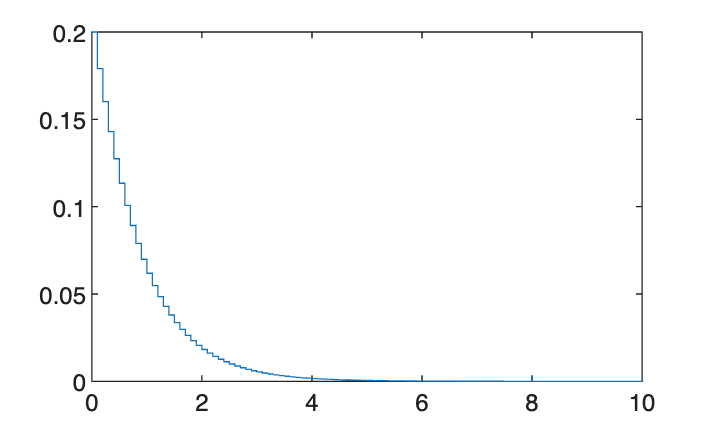


figure
stairs([0:1:100]*Ts, x_traj)

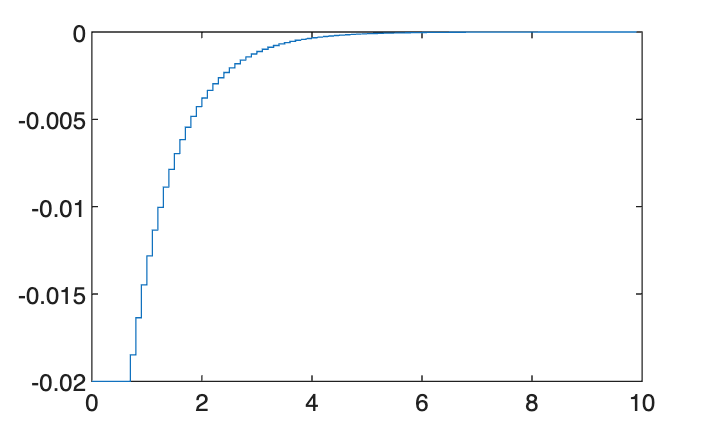


figure
stairs([0:1:99]*Ts, u_traj)

Observe that first u_traj values are exactly equal to our constraints (in particular, they are equal to -0,02) 

NOTE: is not a serendipitous approach (in that case input were cut at limit constraints)

In the remaining time instants, u "is not constrained"

## Exercise 4

**Exercise text removed** (course material, copyright precaution). Topic: Receding-horizon constrained control of a 2-state DT system, Hp=3, given Q=S, R, |u|<=0.6; simulate 500 steps, plot states/input/norm, evaluate zero regulation time.

close all
clear
clc

A = [1 0.0488; 0 0.9512];
B = [0.0012; 0.0488];
p = 1; % input dimension
n = 2; % state dimension
x0 = [-0.8;0];
Ts = 0.05;

Ts = 0.0500


u_sat = 0.6;
Hp = 3;
Q = [100 0; 0 1];
S = Q;
R = 1;

% let's build calligraphic matrices
A_cal = [A;A^2;A^3];
B_cal = [B zeros(n,1) zeros(n,1); A*B B zeros(n,1); A^2*B A*B B];
Q_cal = blkdiag(Q,Q,S);
R_cal = blkdiag(R,R,R);

R_cal =      1     0     0
     0     1     0
     0     0     1



% and matrices for quadratic programming
H = 2*(B_cal'*Q_cal*B_cal + R_cal);
F = 2*A_cal'*Q_cal*B_cal;

G = [eye(3);-eye(3)];
h = u_sat*ones(6,1); 

% forcing symmetry 
H = (H+H')/2; 

x_k = x0; % initial condition
x_traj(:,1) = x0;
sim_steps = 500;

for kk=1:sim_steps
    U = quadprog(H, x_k'*F, G, h); % compute input that optimizes
    x_traj(:,kk+1) = A*x_k+B*U(1);
    u_traj(kk) = U(1);
    x_k = x_traj(:,kk+1);
end


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Minimum found that satisfies the constraints.

Optimization completed because



figure
subplot(311)
stairs(0:Ts:sim_steps*Ts, x_traj(1,:))
xlabel('Time (s)')
ylabel('First State Trajectory')

subplot(312)
stairs(0:Ts:sim_steps*Ts, x_traj(2,:))
xlabel('Time (s)')
ylabel('Second State Trajectory')

subplot(313)
stairs(0:Ts:sim_steps*Ts, sqrt(x_traj(1,:).^2 + x_traj(2,:).^2))
xlabel('Time (s)')
ylabel('State Norm')

figure(2)
stairs(0:Ts:(sim_steps-1)*Ts, u_traj)

## Exercise 5

**Exercise text removed** (course material, copyright precaution). Topic: Same receding-horizon problem with added state constraints x(k+i|k)<=x_max over the horizon.

Now we add state constraints as additional constraint on the input variable

The only difficulty is to write new constraints and stack them in a unique matrix inequality

close all
clear
clc

A = [1 0.0488; 0 0.9512];
B = [0.0012; 0.0488];
p = 1; % input dimension
n = 2; % state dimension
x0 = [-0.8;0];
Ts = 0.05;

u_sat = 0.6;
Hp = 100;
Q = [100 0; 0 1];
S = Q;
R = 1;

[A_cal, B_cal, Q_cal, R_cal] = cal_m_builder(Hp,A,B,R,Q,S);

H = 2*(B_cal'*Q_cal*B_cal + R_cal);
F = 2*A_cal'*Q_cal*B_cal;

% forcing symmetry 
H = (H+H')/2; 

x_k = x0; % initial condition
x_traj(:,1) = x0;
sim_steps = 500;

#### Constraints handle

Now we have to work on constraints

The input constraints are:

Gu = [eye(Hp);-eye(Hp)];
hu = u_sat*ones(2*Hp,1); 

Instead, now we insert the new part (state constraint) 

We can observe that Gx is equal to B caligraphic and hx is equal to A_cal*states + state_constraints

PROBLEM: the state constraint depends on the k-th state value => we must update it at every step in the loop

x_max = [0.00; 0.35];
Gx = B_cal;

for kk=1:sim_steps

    hx = -A_cal*x_k+repmat(x_max, Hp, 1); % repmat replicates the vector x_max according to a matrix with 3 rows (=Hp) and 1 columns
    
    % let's put constraints together
    G = [Gu;Gx];
    h = [hu;hx];

    U = quadprog(H, x_k'*F, G, h); % compute input that optimizes
    x_traj(:,kk+1) = A*x_k+B*U(1);
    u_traj(kk) = U(1);
    x_k = x_traj(:,kk+1);
    
end


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Minimum found that satisfies the constraints.

Optimization completed because

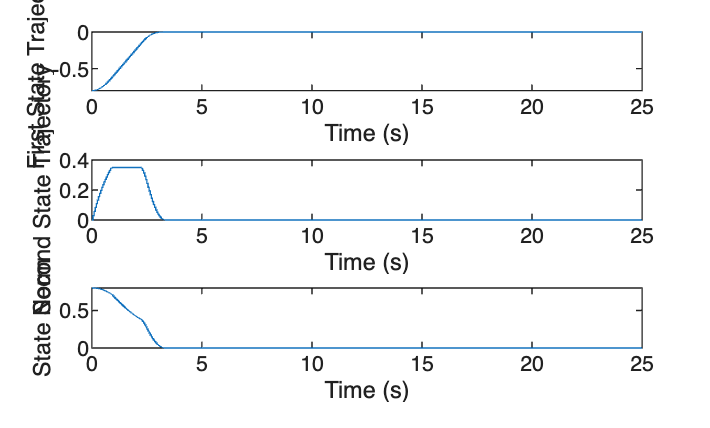



figure
subplot(311)
stairs(0:Ts:sim_steps*Ts, x_traj(1,:))
xlabel('Time (s)')
ylabel('First State Trajectory')

subplot(312)
stairs(0:Ts:sim_steps*Ts, x_traj(2,:))
xlabel('Time (s)')
ylabel('Second State Trajectory')

subplot(313)
stairs(0:Ts:sim_steps*Ts, sqrt(x_traj(1,:).^2 + x_traj(2,:).^2))
xlabel('Time (s)')
ylabel('State Norm')

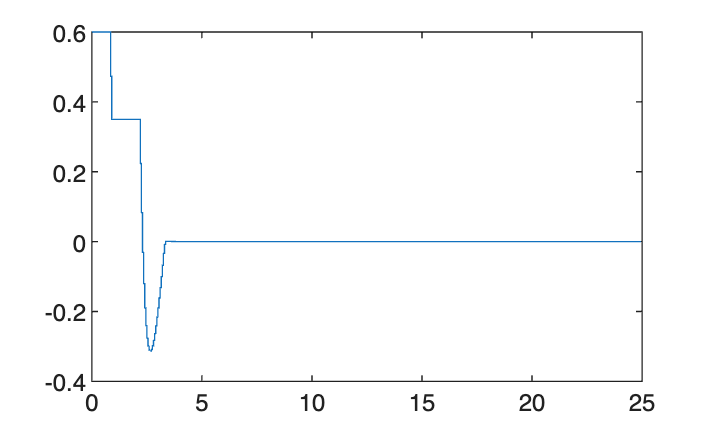


figure
stairs(0:Ts:(sim_steps-1)*Ts, u_traj)

**What happens if we decrease state constraints? **

Let's try with x_max = [0.01;0.35] => we obtain an input that saturates to u_max for certain steps. This is fine, because we stay in our limits and we are able to find the optimal solution

Let's instead try with x_max = [0.00; 0.35] => now quadprog can't find a solution that satisfies our constraints!!!! Because there is no input that optimize the problem and stays in input constraints.

**What can be a possible solution?** -> Increase the prediction horizon!!!! 

Let's consider Hp = 10 -> since we have to recompute everything with new cal_matrices, we just believe it without testing it 

(edit: I could do it with cal_builder function but I like to believe it)